load("H:\data\kwave\result\2018_10_26_no_object_plwv_Correct\freq500kHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_26_no_object_plwv_Correct\freq500kHz\kgrid.mat");
load("H:\data\kwave\config\t_pos_2board.mat")

addpath(genpath('H:/codes/TOF_pickers'))
kgrid.dt

ans = 1.8987e-08

tof_map = threshold_picker_plnwv(rfdata,kgrid,'single');
(t_facing_distance/tof_map)

ans = 1.5800e+03

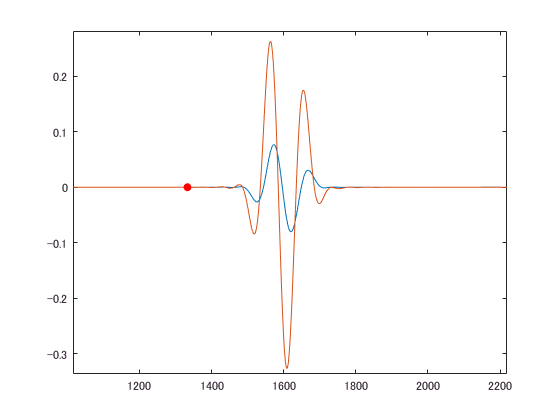

figure;plot(rfdata_sum)
hold on 
plot(rfdata(:,101,1));
scatter(tof_map/kgrid.dt,0,'filled','red');
xlim([1016 2219])
ylim([-0.336 0.281])